clear
M=sym([5/2 sqrt(6)/4])

$$M = \left(\begin{array}{cc} \frac{5}{2} & \frac{\sqrt{2}\,\sqrt{3}}{4} \end{array}\right)$$

N=sym([-2 sqrt(15)/5])

$$N = \left(\begin{array}{cc} -2 & \frac{\sqrt{3}\,\sqrt{5}}{5} \end{array}\right)$$

plot(M(1),M(2),'ro')
hold on
plot(N(1),N(2),'go')
grid on
syms x y a b
Elp1=x^2/a^2+y^2/b^2==1

$$Elp1 = \frac{x^{2}}{a^{2}}+\frac{y^{2}}{b^{2}}=1$$

Eq1=subs(Elp1,[x y],M)

$$Eq1 = \frac{25}{4\,a^{2}}+\frac{3}{8\,b^{2}}=1$$

Eq2=subs(Elp1,[x y],N)

$$Eq2 = \frac{4}{a^{2}}+\frac{3}{5\,b^{2}}=1$$

[a1,b1]=solve(Eq1,Eq2,[a b])

$$a1 = \left(\begin{array}{c} -\sqrt{10}\\ -\sqrt{10}\\ \sqrt{10}\\ \sqrt{10} \end{array}\right)$$

$$b1 = \left(\begin{array}{c} -1\\ 1\\ -1\\ 1 \end{array}\right)$$

Elp2=subs(Elp1,[a b],[a1(4) b1(4)])

$$Elp2 = \frac{x^{2}}{10}+y^{2}=1$$

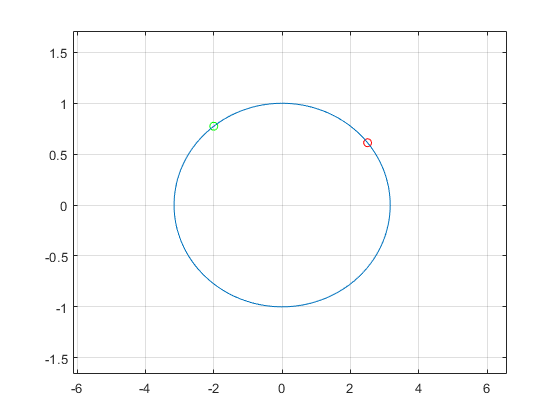

fimplicit(Elp2)

xlim([-6.12 6.58])
ylim([-1.66 1.71])